# Spot diagram

foo

## Visual field position

Given an eye in a particular accommodative state, and given a point in object space, there is a unique location on the retina where that point is imaged (even if that point is the central tendency of a blurred area). What becomes complicated, however, is when we wish to describe the location in object space in terms of *angular visual field* position. With some consideration we come to realize that the assignment of an angular position to a point in object space depends upon specification of points of reference, and that these points of reference can change.

It is often useful to identify points in object space by their visual field position. This is expressed as the horizontal and vertical angles (in, e.g., degrees) of a point in object space with respect to an eye-based coordinate frame. In casual usage, the eye-based coordinate frame may have its origin at the front of the eye, with the horizontal and vertical planes defined with respect to gravity. One advantage of describing locations in terms of visual field position, and size in terms of visual degrees, is that the absolute distance of the object need not be specified.

This simple definition of visual angle is good enough in most circumstances. If, however, greater precision is waranted, then the next stage of complexity is to define visual field position with respect to the* nodal points *of the eye. In a simple, paraxial optical system, a ray directed towards the *incident* node will appear to leave from the optical system at the *emergent* node unchanged in direction of travel (i.e., the incident and emergent rays are parallel). A ray that has the property of entering and exiting an optical system traveling in the same direction is termed a *nodal ray*.

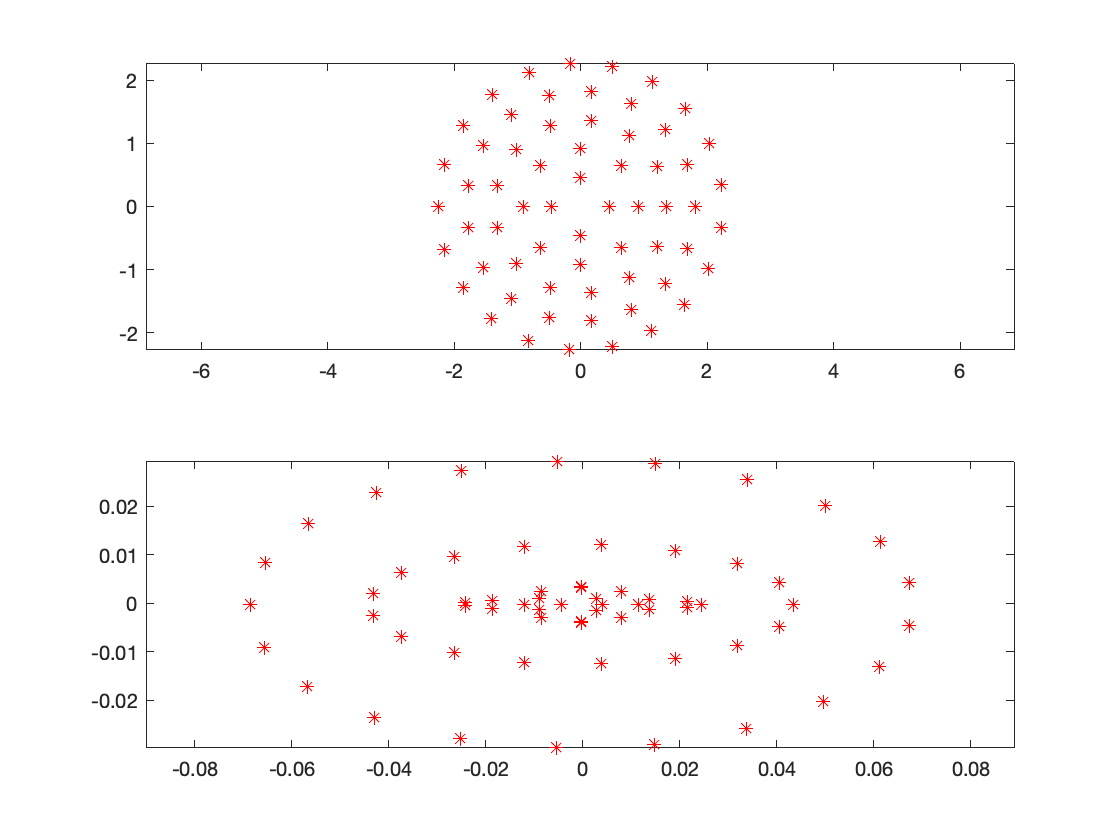

accommodation = 1;
stopRadius = 2;
eye = modelEyeParameters('spectralDomain','vis','accommodation',accommodation);
% Pick a field location
rayOriginDistance = 1000/accommodation;
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
fieldAngularPosition = [0 0];

% Loop over radii
nRings = 5;
scale = linspace(0,1,nRings+1);
scale = scale(2:end);
retinaPoints = [];
rayPaths = {};
for rr = 1:nRings
    nStopPerimPoints = round(21 .* scale(rr));
    thisRadius = stopRadius * scale(rr);
    [tempPoints,tempPaths] = calcRayBundleFromField(eye,fieldAngularPosition,thisRadius,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord,nStopPerimPoints);
    retinaPoints = [retinaPoints, tempPoints];
    rayPaths = [rayPaths, tempPaths];
end

% Extract the ray positions as they intersect the cornea
corneaPoints = cell2mat(cellfun(@(x) x(:,2),rayPaths,'UniformOutput',false));

% Plot the spot diagram
figure;
subplot(2,1,1); plot(corneaPoints(2,:),corneaPoints(3,:),'*r'); axis equal
subplot(2,1,2); plot(retinaPoints(2,:),retinaPoints(3,:),'*r'); axis equal

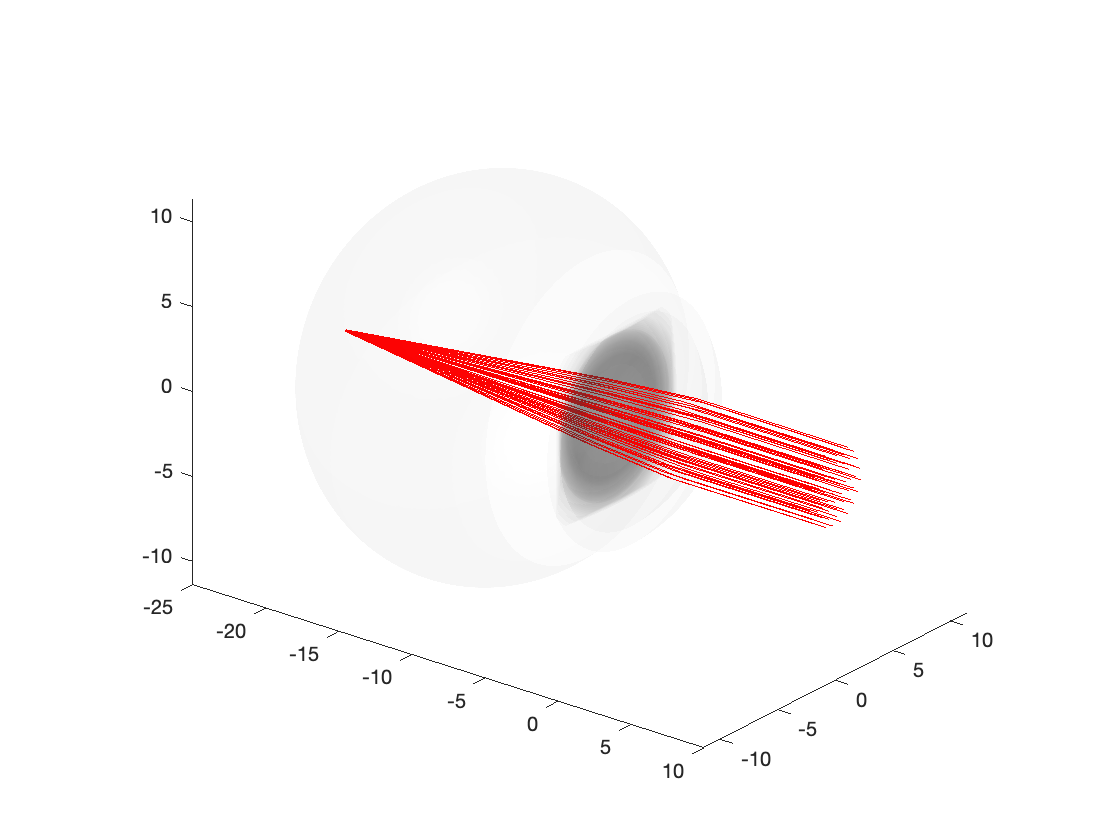


% Plot the optical system
opticalSystem = assembleOpticalSystem(eye,'surfaceSetName','mediumToRetina');
figure
plotOpticalSystem('newFigure',false,'surfaceSet',opticalSystem,'addLighting',true,'surfaceAlpha', 0.05);
% Add the rays to the plot
for ii=1:length(rayPaths)
    plotOpticalSystem('newFigure',false,'rayPath',rayPaths{ii});
end
xlim([-25 10]);